Figures

Dependecies: 

- pangyuteng (2021). Convert Voronoi cells to region mask (https://www.mathworks.com/matlabcentral/fileexchange/43032-convert-voronoi-cells-to-region-mask), MATLAB Central File Exchange. Retrieved April 14, 2021.

Select which plots to generate:

% Generate color-coded spatial map of hair follicle orientations
runAngleMap =  true;
% Generate map of local order
runOrderMap =  true;
% If generating a local order plot, select a value to calculate the search radius (multiple of the average distance between two follicles):
r = 2;
% Adds a labeled colorbar to angle and order plots
showColorbar = true;
% Generate dot plot of angles vs AP axis
runAPdotPlot =  true;
% Generate dot plot with multiple samples. If selected, a second pop-up window will
% prompt the user to select two or more .csv files to generate this plot
runMultiAPdotPlot = false;
% Color of dot plots
plotcolor = '#666666';

%If runWithExampleData is checked, select a distribution of angles to use.
runWithExampleData = true;
angledist = "Wildtype"; 

 

% % Input: 
% if any plots are selected, ask user to select input file. If not throw error.
if (runAPdotPlot | runAngleMap | runOrderMap) == false
    error("Please select a plot to run.")
end

if (runAngleMap | runOrderMap) == true && ~runWithExampleData
    % Load data from fiji output
    cd(userpath)
    [datafile, path] = uigetfile('*.csv');
    addpath(path);
    fijidata = readtable([path datafile]);
    % Convert Fiji results to usable data matrix
    Data = zeros(size(fijidata,1), 4);
    Data(:,1) = fijidata.X;     % X
    Data(:,2) = fijidata.Y;     % Y
    Data(:,3) = fijidata.Angle; % Angle (-180–-180)
    Data(:,4) = fijidata.Length>0;  % is there a length (measurement for downgrown will have length==0)
    % change angle value for downgrown follicles to -1 to aid visualization
    % (for colormap) and convert angles to 0-360
    Data(Data(:,4)==0,3)= -181;
    Data(:,3) = Data(:,3)+180;  % shift angle to 0:360 to get angle relative to AP axis
    % Extract key values
    imsize = ceil(Data(1, 1:2))*2;      % size of original image [x y] stored as last value in follicleData
    Data = Data(2:size(Data),:);               % remove size measurement from dataset
    Data = sortrows(Data);
end

if (runAngleMap || runOrderMap) == true && runWithExampleData
    grid_size = 250;
    Data = generate_exampledata(grid_size,angledist);
    imsize = [6000 2150];
end

Dot plot (angle vs A-P position)

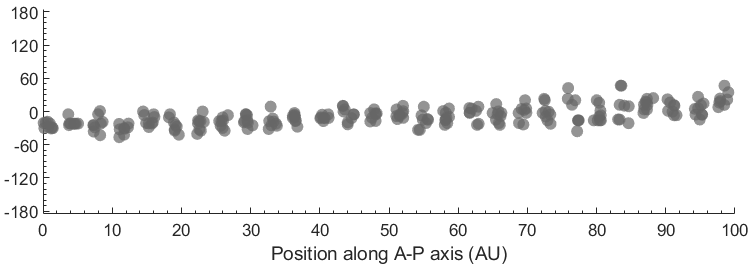

if runAPdotPlot == true
    % plot of angle by A-P position (x-coord)
    AP = figure;
    angle180 = mod(Data(Data(:,4)==1,3)+180, 360)-180; % shift angle to fit -180:180 frame without changing values
    scatter(Data(Data(:,4)==1,1)/imsize(1)*100, angle180,'MarkerFaceColor',plotcolor, 'MarkerEdgeColor',"none", 'MarkerFaceAlpha', .7);
    xlabel('Position along A-P axis (AU)');
    % ylabel('Follicle angle (degrees)');
    yticks(-180:60:180);
    ax = gca;
    ax.YLim = [-185 185];
    ax.XLim = [0 100];
    ax.XMinorTick = true;
    ax.YMinorTick = true;
    AP.Position(3:4) = [imsize(1)/imsize(1)*500, imsize(2)/imsize(1)*500];
    outerpos = ax.OuterPosition;
    ti = ax.TightInset; 
    left = outerpos(1) + ti(1);
    bottom = outerpos(2) + ti(2);
    ax_width = outerpos(3) - ti(1) - ti(3);
    ax_height = outerpos(4) - ti(2) - ti(4);
    ax.Position = [left bottom ax_width ax_height];
    ax.Color = 'none';   
end

clf('reset')

if runMultiAPdotPlot == true
    [multidatafiles, multipath] = uigetfile('Images/Maureen/*.csv', 'MultiSelect', 'on');
    if class(multidatafiles) == 'char'
       error("Must select multiple files as input or uncheck 'runMultiAPdotPlot'.") 
    end
 
    n = length(multidatafiles);
    multiData = cell(n,1);
    AP = figure;
    imsizemulti = [0 0];
    hold on
    for i=1:n
        indata = readtable([multipath multidatafiles{i}]);
        % Convert Fiji results to usable data matrix
        outdata = zeros(size(indata,1), 4);
        outdata(:,1) = indata.X;
        outdata(:,2) = indata.Y;
        outdata(:,3) = indata.Angle;
        outdata(:,4) = indata.Length>0;
        % set 'imsizemulti' to largest image size from this set
        if imsizemulti(1) < ceil(outdata(1, 1))*2
            imsizemulti(1) = ceil(outdata(1, 1))*2;
        end
        if imsizemulti(2) < ceil(outdata(1, 2))*2
            imsizemulti(2) = ceil(outdata(1, 2))*2;
        end
        outdata = outdata(2:size(outdata),:);            % remove size measurement from dataset
        outdata = sortrows(outdata);
        alpha = .9-.1*i;
        angle180 = mod(outdata(outdata(:,4)==1,3), 360)-180;
        scatter(outdata(outdata(:,4)==1,1)/imsizemulti(1)*100, angle180,'MarkerFaceColor',plotcolor, 'MarkerEdgeColor',"none", 'MarkerFaceAlpha', alpha);
    end
    xlabel('Position along A-P axis (AU)');
    % ylabel('Follicle angle (degrees)');
    yticks(-180:60:180);
    ax = gca;
    ax.YLim = [-185 185];
    ax.XLim = [0 100];
    ax.XMinorTick = true;
    ax.YMinorTick = true;
    AP.Position(3:4) = [imsizemulti(1)/imsizemulti(1)*500, imsizemulti(2)/imsizemulti(1)*500];
    outerpos = ax.OuterPosition;
    ti = ax.TightInset;
    left = outerpos(1) + ti(1);
    bottom = outerpos(2) + ti(2);
    ax_width = outerpos(3) - ti(1) - ti(3);
    ax_height = outerpos(4) - ti(2) - ti(4);
    ax.Position = [left bottom ax_width ax_height];
    ax.Color = 'none';
end

if (runAngleMap | runOrderMap) == true
    % create a mask based on voronoi diagrams, using centroids in grown as the seed points
    mask = voronoi2mask(Data(:,1),Data(:,2),[imsize(2), imsize(1)]);
    mask = imerode(mask, [strel('line', 3, 0), strel('line', 3, 90)]);
end

Voronoi angle diagram

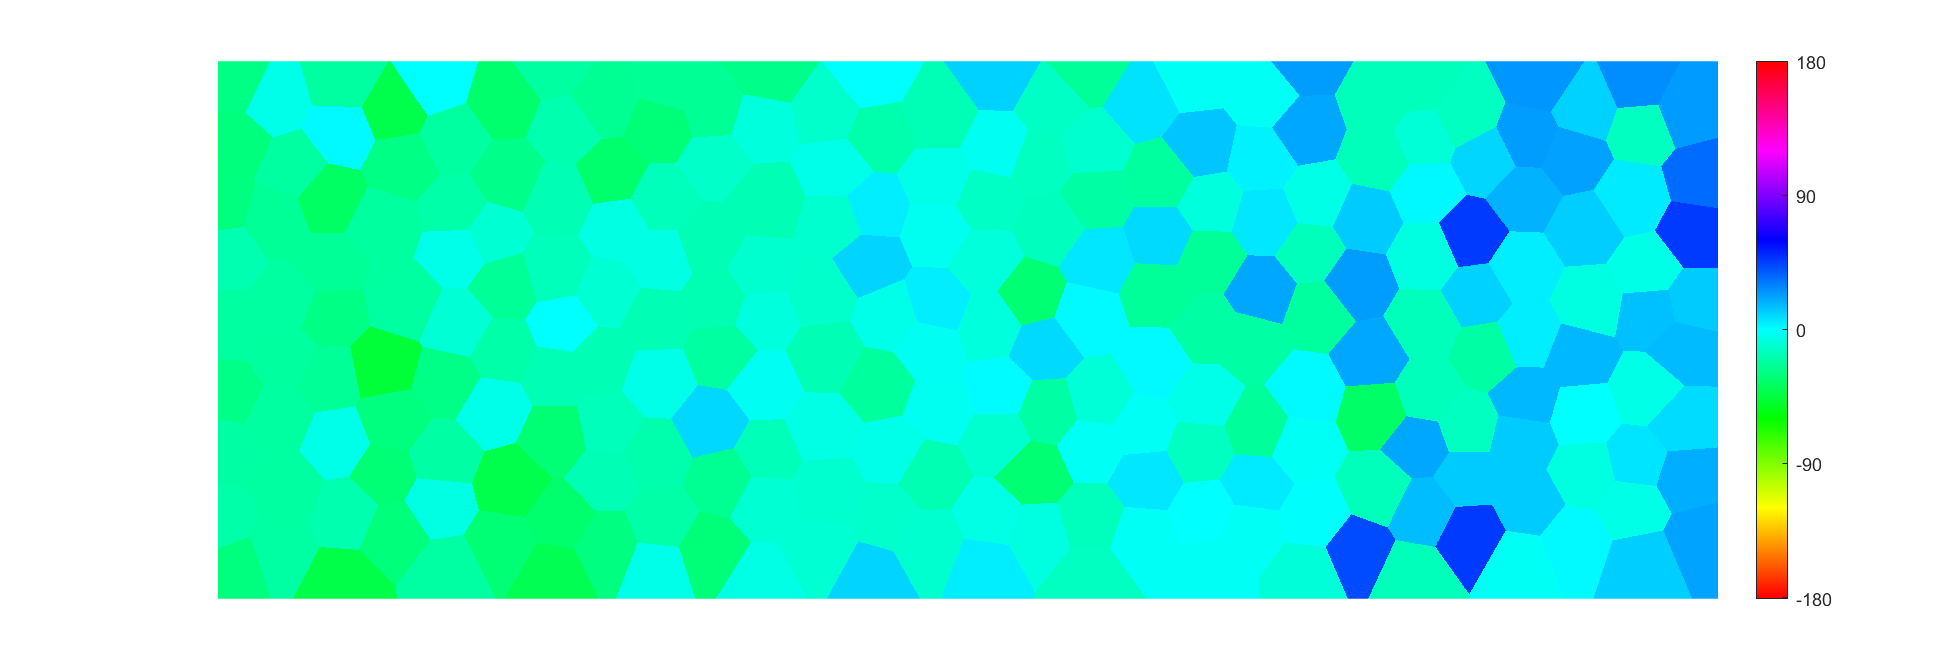

if runAngleMap == true
    % define 0:360 angle colormap
    n = 720;        % two colors defined per angle for an even distribution
    % offsets the hsv colormap to center 0° at cyan
    cmap = hsv2rgb(horzcat(((0:n)./n)', repelem(1, n+1)', repelem(1, n+1)'));  % 0° = cyan
    % adds zeros to correspond to negative numbers (ie NaNs, to color black)
    cmap = vertcat([0 0 0; 0 0 0], cmap);
    % creates a masked image with voronoi cells color-coded by angle
    maskcmap = voronoiangle(mask, Data);
    
    % display voronoi diagram colored by angle
    anglemap = figure;
    imshow(maskcmap);           
    colormap(cmap);
    caxis([-1 360])
    if showColorbar == true
        colorbar
        colorbar('Ticks', [0,90,180,270,360], 'TickLabels', [-180,-90,0,90,180]);
    end 
    truesize(gcf, [imsize(2)/6 imsize(1)/6])      % display at 1/6 resolution because it fits on screen
end

Voronoi order diagram

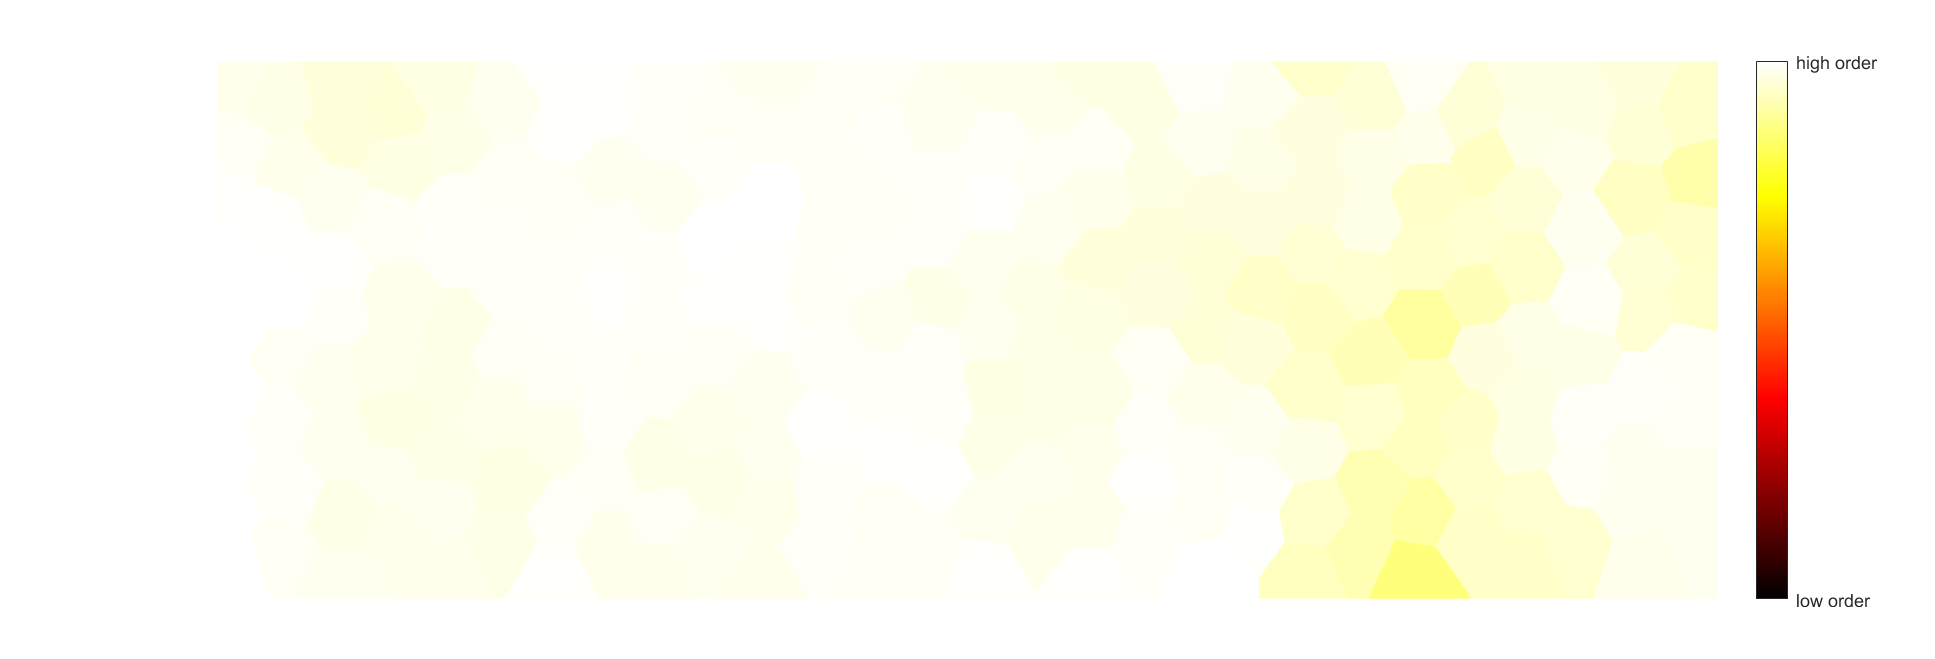

if runOrderMap == true
    numneighbors = 1;
    % creates a masked image with voronoi cells color-coded by local order
    % numneighbors is used to calculate ave. distance to the nearest 'numneighbors' neighbors
    % r is the multiple used to calculate the search radius using this
    % average distance. Set both above.
    % search radius = r * ave. distance
    [omaskcmap, avedist, Idx] = voronoiorder(mask, Data, numneighbors, r);
    % display
    ordermap = figure;
    imshow(omaskcmap);
    colormap(hot)
    if showColorbar == true
        colorbar('Ticks', [0, 1], 'TickLabels', [{'low order'}, {'high order'}])
    end
    truesize(gcf, [imsize(2)/6 imsize(1)/6])      % display at 1/6 resolution because it fits on screen
end

function [maskcmap] = voronoiangle(mask, Data)
maskcmap = mask;
% create heatmap by angle
for i = 1:size(Data, 1)
    if Data(i,4)==0
        angleLabel = Data(i,3);
    elseif Data(i,4)==1
        angleLabel = mod(Data(i,3)+180,360);
    end
    maskcmap(maskcmap==i) = angleLabel+0.01; % adjust to distinguish values from labels
end
maskcmap = maskcmap-0.01; % undo adjustment to recover real values
end


function [omaskcmap, avedist, Idx] = voronoiorder(mask, Data, numneighbors, r)
% Order parameter calculation: uses matrix w downgrown points, but excludes 
% from analysis. these will be black in final map
[~, dist] = knnsearch(Data(:,1:2), ...
    Data(:,1:2), 'K', numneighbors+1);                 % find distances to nearest neighbor(s)
avedist = mean(dist(:,2:numneighbors+1), 'all');        % average distance to n nearest neighbors
Idx = rangesearch(Data(Data(:,4)==1,1:2),Data(Data(:,4)==1,1:2),r*avedist);
% associate Idx index with 'Data' table index
k = 1;
for i = 1:(size(Data,1))
    if Data(i,4)==1
        Idx{k,2} = i;
        k = k+1;
    end
end
% calculate order parameter
order = zeros([size(Data,1),1], 'double');
for i = 1:size(Idx,1)
    ordertotal = 0;
    count = 0;
    for j = 1:size(Idx{i,1},2)-1
        for k = (j+1):size(Idx{i,1},2)
            ordertotal = ordertotal + ...
                (cosd(Data(Idx{Idx{i,1}(j),2},3) - Data(Idx{Idx{i,1}(k), 2},3))+1)./2;
            count = count+1;
        end
    end
    order(Idx{i,2}, 1) = ordertotal./count;
end

% convert labels in mask to the order value
omaskcmap = mask;
for i = 1:size(Data, 1)
    omaskcmap(omaskcmap==i) = order(i, 1);
end
end
